# Advanced micro wave lab - experimants 1 and 2 

# Experimant 2

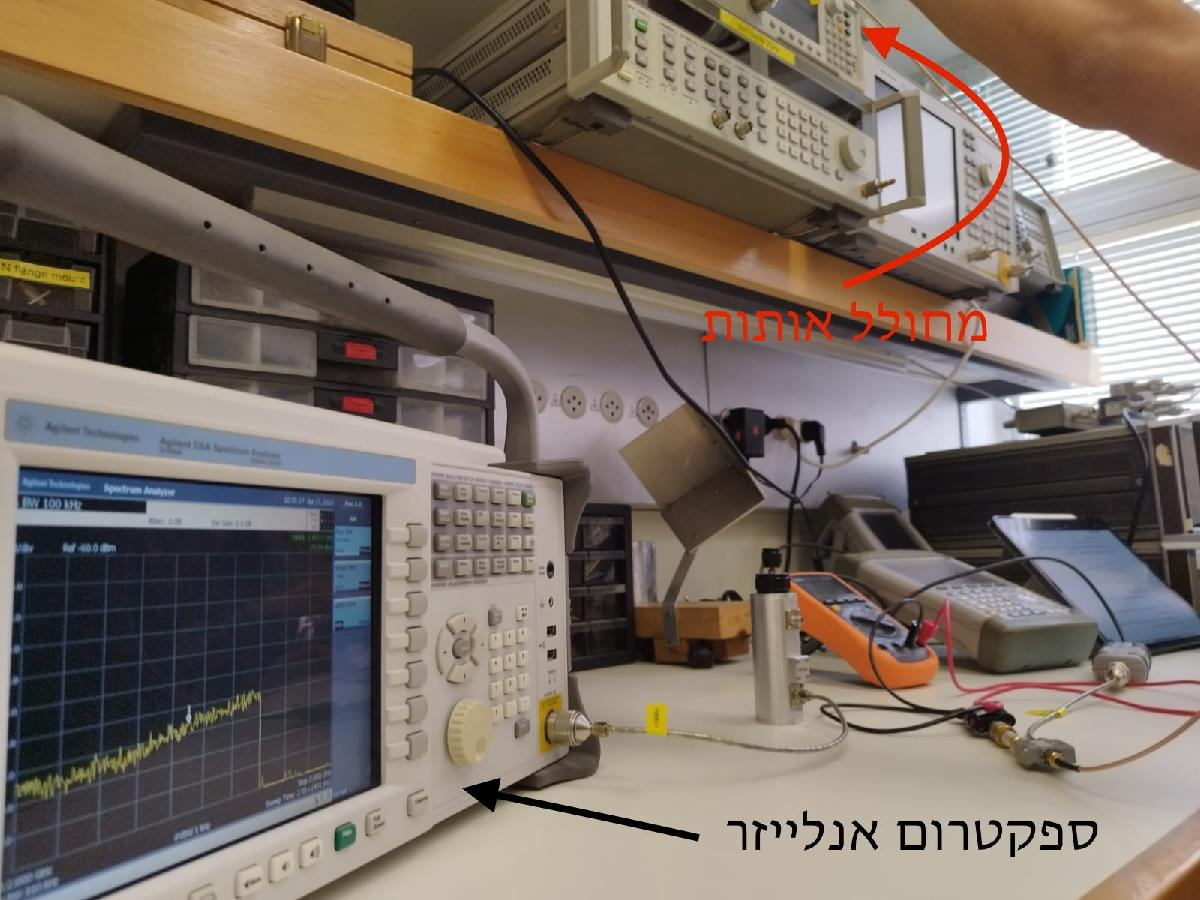

## 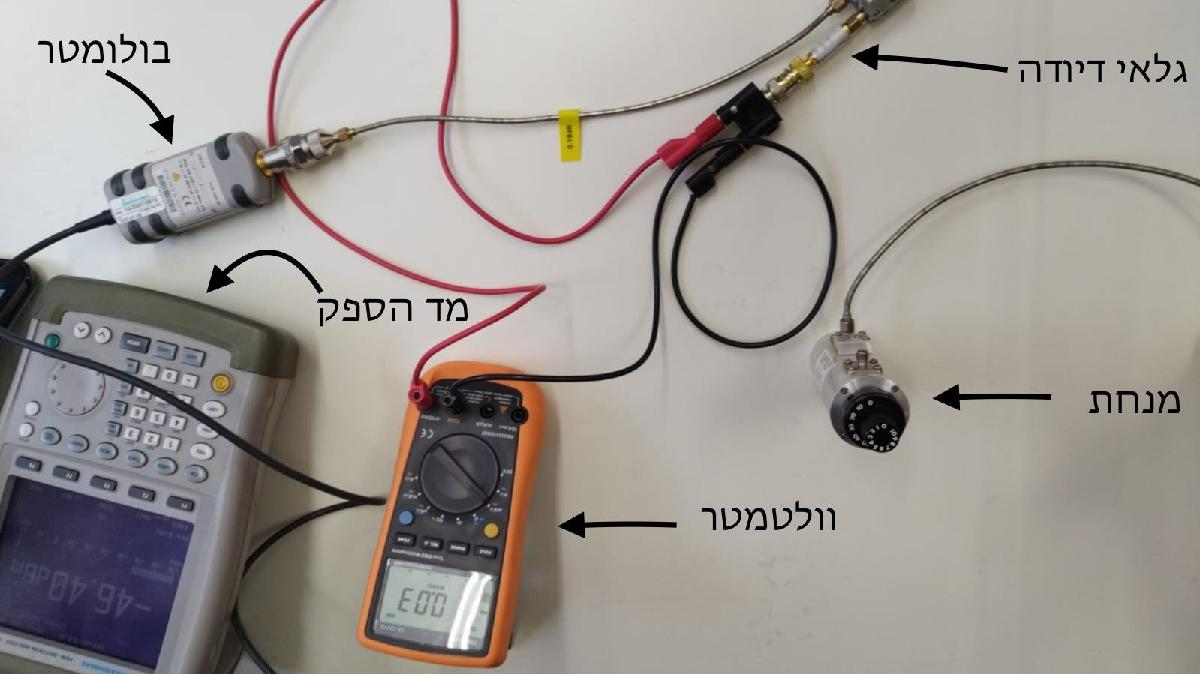

## Section 1 - measurements devices

measurements

power_dbm_input=[0.04,0.04,0.06,0.11,0.28,0.76,1.17,1.83,2.9,...	  
4.67,7.49,9.44,11.91,14.99,19.08,23.71]	;
power_dbm_output=[-46.3,-36.75,-31.85,-26.9,-21.89,-16.74,-14.4,...
-12.13,-10.12,-8.05,-6.06,-5.1,-4.11,-3.14,-2.08,-1.11];
Voltage_mV =[0.04,0.04,0.06,0.11,0.28,0.76,1.17,1.83,2.9,4.67,...
7.49,9.44,11.91,14.99,19.08,23.71];
T1 = table(power_dbm_input', power_dbm_output',Voltage_mV', 'VariableNames', {'Power dbm input', 'Power dbm output','Voltage mV'})

T1 = 16×3 table
    Power dbm input    Power dbm output    Voltage mV
    _______________    ________________    __________

          0.04               -46.3            0.04   
          0.04              -36.75            0.04   
          0.06              -31.85            0.06   
          0.11               -26.9            0.11   
          0.28              -21.89            0.28   
          0.76              -16.74            0.76   
          1.17               -14.4            1.17   
          1.83              -12.13            1.83   
           2.9              -10.12             2.9   
          4.67               -8.05            4.67   
          7.49               -6.06            7.49   
          9.44                -5.1            9.44   
         11.91               -4.11           11.91   
         14.99               -3.14           14.99   
         19.08   

Plot

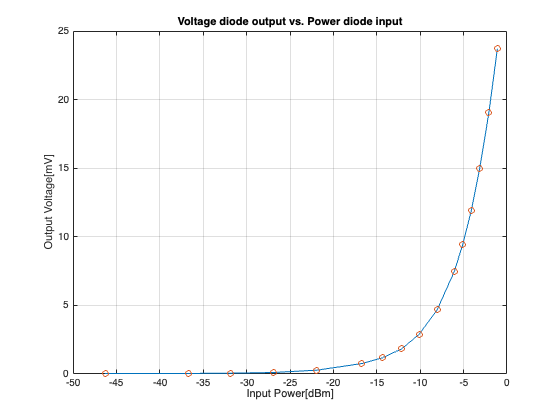

figure;
plot(power_dbm_output,Voltage_mV)
hold on 
scatter(power_dbm_output,Voltage_mV)
grid on 
title('Voltage diode output vs. Power diode input')
xlabel('Input Power[dBm]')
ylabel('Output Voltage[mV]')

% saveas(gcf, '/Users/ohadformanair/Documents/Git/AML/LAB_1p2/Plots/VOlt_vs_power.png', 'png');
Exponential_fit(power_dbm_output, Voltage_mV)

ans =      General model Exp1:
     ans(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       30.78  (30.55, 31.01)
       b =      0.2316  (0.2292, 0.2339)

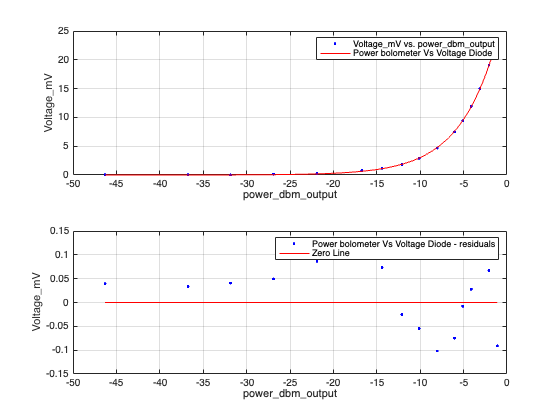

saveas(gcf, '/Users/ohadformanair/Documents/Git/AML/LAB_1p2/Plots/V_vs_P.png', 'png');

Fitareaof2nd(power_dbm_output, Voltage_mV)

ans =      General model:
     ans(x) = (b*x-a)^(2)+3
     Coefficients (with 95% confidence bounds):
       a =          -5  (fixed at bound)
       b =         0.5  (fixed at bound)

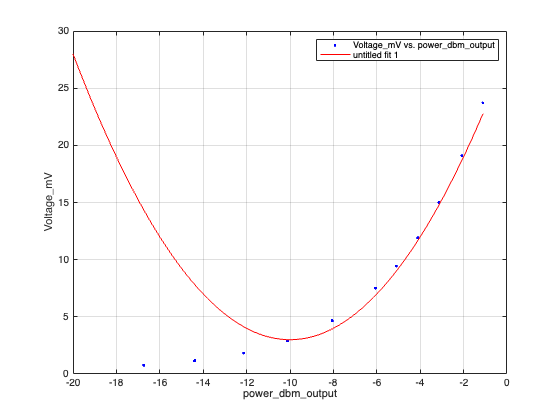

xlim([-20,0])

## Section 2 - Noise Vs RBW

RBW

RBW = [1e3,10e3,100e3,510e3,1e6,5e6];
noise_level = [-80.13,-78.9,-77.56,-75.88,-72.72,-66];
T2 = table(RBW', noise_level', 'VariableNames', {'RBW', 'Noise_Level'})

T2 = 6×2 table
      RBW      Noise_Level
    _______    ___________

       1000      -80.13   
      10000       -78.9   
      1e+05      -77.56   
    5.1e+05      -75.88   
      1e+06      -72.72   
      5e+06         -66   


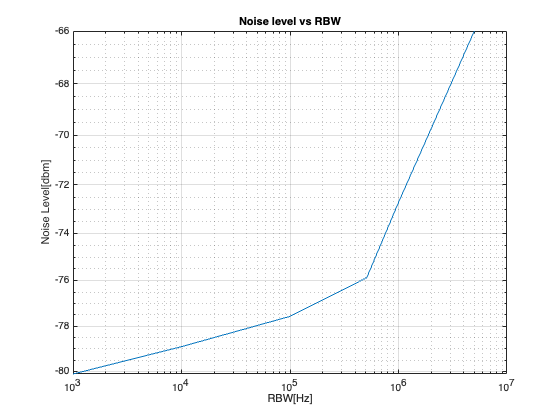

figure;
loglog(RBW,noise_level)
xlabel('RBW[Hz]')
ylabel('Noise Level[dbm]')
title('Noise level vs RBW')
grid on

% saveas(gcf, '/Users/ohadformanair/Documents/Git/AML/LAB_1p2/Plots/Noise_vs_DBW.png', 'png');

# Experimant 1

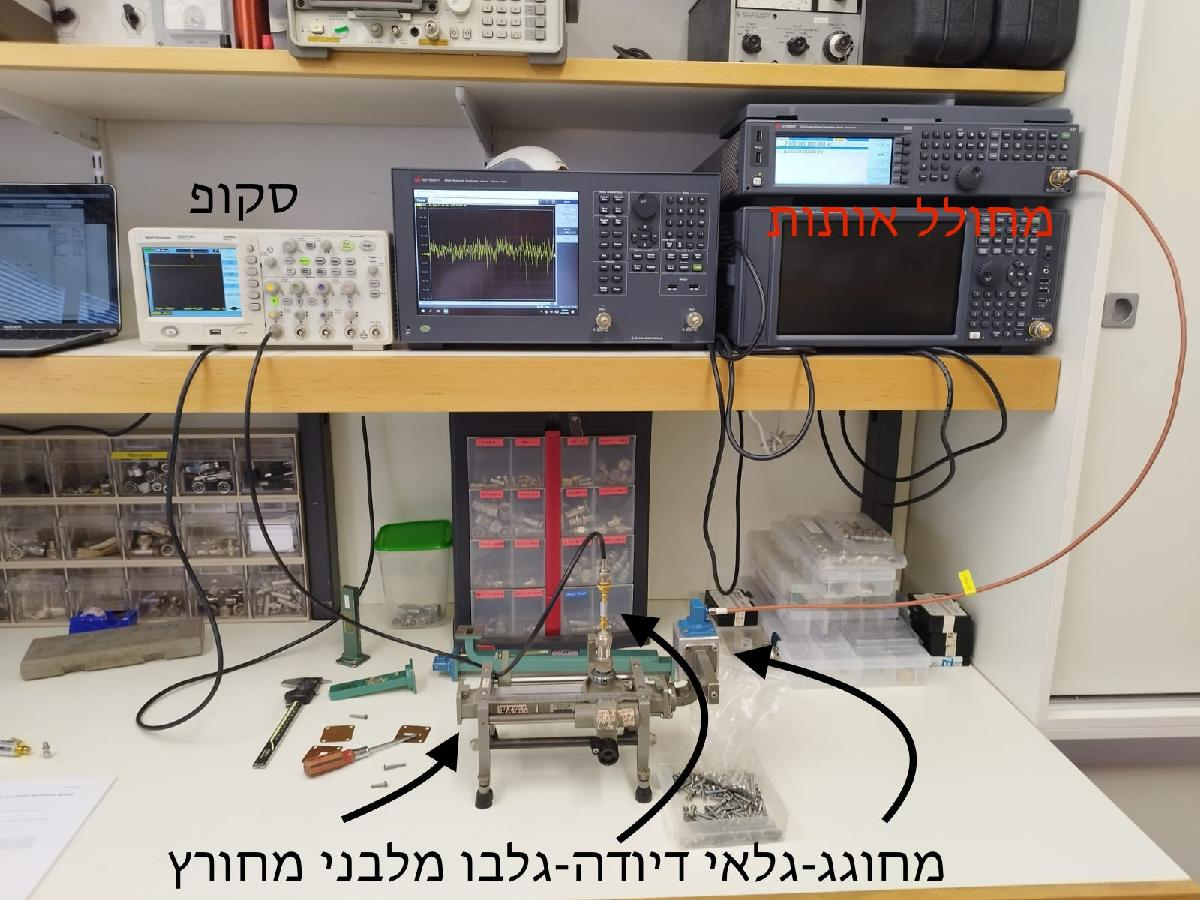

`wave guide dimensions - a=22.68 b=9.93`

## **Section 1 - loads, wave patterns **

Length = [8.5,9.5,10.5,11.5,12.5,13.5,14.5,15.5,16.5,17.5,18.5];

Capacity_voltage_mv=[-2.48,-3.24,-5.1,-2.45,-3.17,-5.17,-2.33,-3.12,-5.16,-2.4,-3.27];
cap_power = Volt_to_power(Capacity_voltage_mv);

Inductance_voltage_mv = [-5.38,-19,-4.86,-6,-19.1,-5.15,-5.94,-19.3,-5.01,-5.84,-19.1];
Inductance_power = Volt_to_power(Inductance_voltage_mv);

short_voltage_mv = [-0.95,-10.7,-6.3,-0.8,-10.8,-6.41,-0.91,-10.9,-6.42,-0.96,-10.7];
short_power = Volt_to_power(short_voltage_mv);

short_voltage_mv_8Ghz=[-19.8,-5.33,-4.77,-18.9,-11.8,-1.51,-15.2,-17.6,-1.43,-10,-19.9];
short8Ghz_power = Volt_to_power(short_voltage_mv_8Ghz);

Open_voltage_mv =[-3.1,-3.03,-4.76,-3.1,-3,-4.78,-3.12,-2.95,-4.73,-3.05,-2.94];
Open_power = Volt_to_power(Open_voltage_mv);

matched_voltage_mv =[-3.9,-4.2,-4.27,-3.88,-4.22,-4.26,-3.89,-4.2,-4.26,-3.91,-4.12];
matched_power = Volt_to_power(matched_voltage_mv);

T3 = table(Length', Capacity_voltage_mv',Inductance_voltage_mv',short_voltage_mv',...
    short_voltage_mv_8Ghz',Open_voltage_mv',matched_voltage_mv', 'VariableNames', {'Length', 'Capacity_voltage_mv',...
    'Inductance_voltage_mv','short_voltage_mv','short_voltage_mv_8Ghz','Open_voltage_mv','matched_voltage_mv'})

T3 = 11×7 table
    Length    Capacity_voltage_mv    Inductance_voltage_mv    short_voltage_mv    short_voltage_mv_8Ghz    Open_voltage_mv    matched_voltage_mv
    ______    ___________________    _____________________    ________________    _____________________    _______________    __________________

      8.5            -2.48                   -5.38                 -0.95                  -19.8                  -3.1                -3.9       
      9.5            -3.24                     -19                 -10.7                  -5.33                 -3.03                -4.2       
     10.5             -5.1                   -4.86                  -6.3                  -4.77                 -4.76               -4.27       
     11.5           

T3_power = table(Length', cap_power',Inductance_power',short_power',...
    short8Ghz_power',Open_power',matched_power', 'VariableNames', {'Length', 'Capacity_power_dBm',...
    'Inductance_power_dBm','short_power_dBm','short_power_dBm_8Ghz','Open_power_dBm','matched_power_dBm'})

T3_power = 11×7 table
    Length    Capacity_power_dBm    Inductance_power_dBm    short_power_dBm    short_power_dBm_8Ghz    Open_power_dBm    matched_power_dBm
    ______    __________________    ____________________    _______________    ____________________    ______________    _________________

      8.5           17.331                 8.8539               24.701               0.31386               15.013             12.474      
      9.5           14.534                0.37775               2.5825                 8.957               15.258             11.636      
     10.5           9.4471                  9.987               7.1548                10.197               10.221             11.449      
     11.5           17.452                 7

% Calculate the values
VSWR_cap = sqrt(max(T3_power{:,'Capacity_power_dBm'})/min(T3_power{:,'Capacity_power_dBm'}));
VSWR_ind = sqrt(max(T3_power{:,'Inductance_power_dBm'})/min(T3_power{:,'Inductance_power_dBm'}));
VSWR_short12 = sqrt(max(T3_power{:,'short_power_dBm'})/min(T3_power{:,'short_power_dBm'}));
VSWR_short8 = sqrt(max(T3_power{:,'short_power_dBm_8Ghz'})/min(T3_power{:,'short_power_dBm_8Ghz'}));
VSWR_open = sqrt(max(T3_power{:,'Open_power_dBm'})/min(T3_power{:,'Open_power_dBm'}));
VSWR_matched = sqrt(max(T3_power{:,'matched_power_dBm'})/min(T3_power{:,'matched_power_dBm'}));
Z0_8Ghz = 120*pi/(1-(6.6093/8)^2)

Z0_8Ghz = 1.1875e+03

Z0_12Ghz = 120*pi/(1-(6.6093/12)^2)

Z0_12Ghz = 541.1509

gamma_cap = (VSWR_cap-1)/(VSWR_cap+1);
gamma_ind = (VSWR_ind-1)/(VSWR_ind+1);
gamma_short12 = (VSWR_short12-1)/(VSWR_short12+1);
gamma_short8 = (VSWR_short8-1)/(VSWR_short8+1);
gamma_open = (VSWR_open-1)/(VSWR_open+1);
gamma_matched = (VSWR_matched-1)/(VSWR_matched+1);
ZL_cap = (1+gamma_cap)/(1-gamma_cap)*Z0_12Ghz;
ZL_ind = (1+gamma_ind)/(1-gamma_ind)*Z0_12Ghz;
ZL_short12 = (1+gamma_short12)/(1-gamma_short12)*Z0_12Ghz;
ZL_short8 = (1+gamma_short8)/(1-gamma_short8)*Z0_8Ghz;
ZL_open = (1+gamma_open)/(1-gamma_open)*Z0_12Ghz;
ZL_matched = (1+gamma_matched)/(1-gamma_matched)*Z0_12Ghz;

% Create a table with the calculated values
T = table({'cap'; 'ind'; 'short12'; 'short8'; 'open'; 'matched'},...
          [VSWR_cap; VSWR_ind; VSWR_short12; VSWR_short8; VSWR_open; VSWR_matched],...
          [ZL_cap; ZL_ind; ZL_short12; ZL_short8; ZL_open; ZL_matched],...
          [gamma_cap; gamma_ind; gamma_short12; gamma_short8; gamma_open; gamma_matched],...
          'VariableNames',{'Element', 'VSWR', 'ZL', 'Gamma'})

T = 6×4 table
      Element       VSWR       ZL       Gamma  
    ___________    ______    ______    ________

    {'cap'    }    1.3894    751.88     0.16297
    {'ind'    }    5.3236    2880.9     0.68373
    {'short12'}    3.2206    1742.9     0.52614
    {'short8' }    8.4895     10082     0.78924
    {'open'   }    1.2375    669.66     0.10613
    {'matched'}    1.0462    566.15    0.022577


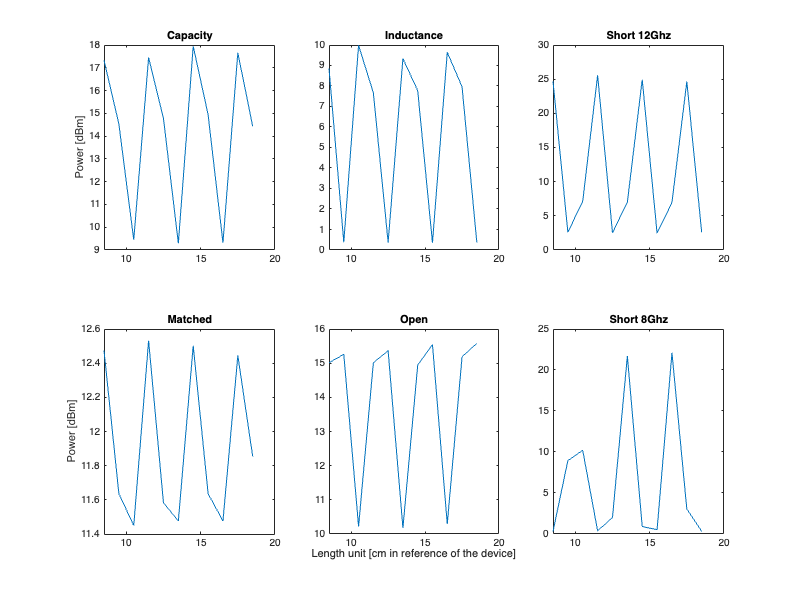

table2latex(T,'result_waves')


% Set the figure size
fig = figure('Position', [100 100 800 600]);

% Create subplots
subplot(2,3,1);
plot(Length,cap_power)
title('Capacity')
ylabel('Power [dBm]')
subplot(2,3,2);
plot(Length,Inductance_power)
title('Inductance')
subplot(2,3,3);
plot(Length,short_power)
title('Short 12Ghz')
subplot(2,3,4);
plot(Length,matched_power)
title('Matched')
ylabel('Power [dBm]')
subplot(2,3,5);
plot(Length,Open_power)
title('Open')
xlabel('Length unit [cm in reference of the device]')
subplot(2,3,6);
plot(Length,short8Ghz_power)
title('Short 8Ghz')

Fit

figure;
Sine_sum_fit(Length,abs(Capacity_voltage_mv))

ans =      General model Sin3:
     ans(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3)
     Coefficients (with 95% confidence bounds):
       a1 =      -5.239  (-7191, 7180)
       b1 =     0.06243  (-92.43, 92.55)
       c1 =       3.416  (-1477, 1484)
       a2 =      -1.545  (-7274, 7270)
       b2 =      0.1498  (-159.9, 160.2)
       c2 =       5.108  (-2621, 2631)
       a3 =      -1.633  (-1.816, -1.45)
       b3 =       2.095  (2.056, 2.135)
       c3 =       8.119  (7.588, 8.65)

cap_coe = 1.545/5.239

cap_coe = 0.2949

SWR_cap=(1+cap_coe)/(1-cap_coe)

SWR_cap = 1.8365

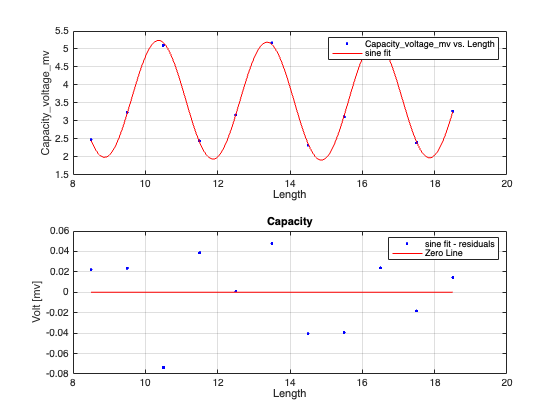

title('Capacity')
ylabel('Volt [mv]')

figure;

Sine_sum_fit(Length,abs(Inductance_voltage_mv))

ans =      General model Sin3:
     ans(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3)
     Coefficients (with 95% confidence bounds):
       a1 =      0.1212  (-0.007174, 0.2495)
       b1 =       2.748  (2.35, 3.146)
       c1 =      -29.83  (-35.37, -24.29)
       a2 =       10.13  (10.03, 10.22)
       b2 =      0.0548  (0.03893, 0.07066)
       c2 =       7.072  (6.87, 7.275)
       a3 =       9.167  (9.059, 9.275)
       b3 =       2.097  (2.09, 2.103)
       c3 =       6.835  (6.756, 6.914)

ind_coe=9.167/10.13

ind_coe = 0.9049

SWR_ind=(1+ind_coe)/(1-ind_coe)

SWR_ind = 20.0384

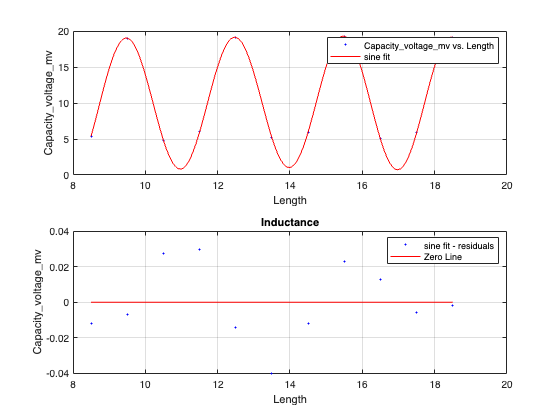

title('Inductance')

figure;

Sine2sum(Length,short_voltage_mv)

ans =      General model Sin2:
     ans(x) =  a1*sin(b1*x+c1) + a2*sin(b2*x+c2)
     Coefficients (with 95% confidence bounds):
       a1 =       6.048  (5.944, 6.152)
       b1 =     0.02257  (-0.03882, 0.08397)
       c1 =       4.339  (3.674, 5.004)
       a2 =       5.707  (5.61, 5.804)
       b2 =       2.093  (2.085, 2.1)
       c2 =      -3.178  (-3.275, -3.081)

short_coe = 5.707/6.048

short_coe = 0.9436

SWR_short12=(1+short_coe)/(1-short_coe)

SWR_short12 = 34.4721

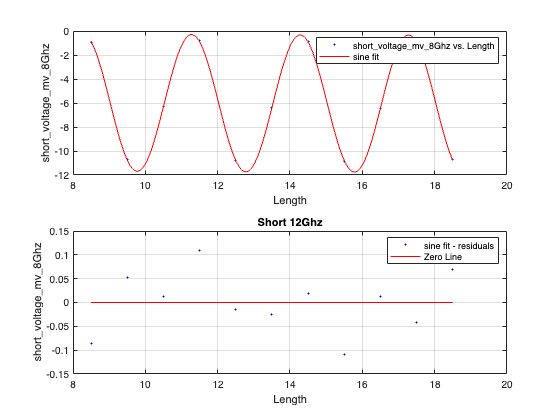

title('Short 12Ghz')

figure;

Sine_sum_fit(Length,abs(matched_voltage_mv))

ans =      General model Sin3:
     ans(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3)
     Coefficients (with 95% confidence bounds):
       a1 =      -7.161  (-6854, 6839)
       b1 =      0.1299  (-43.92, 44.18)
       c1 =       3.061  (-556.7, 562.8)
       a2 =       3.046  (-6843, 6850)
       b2 =       0.203  (-68.43, 68.83)
       c2 =       8.415  (-863.3, 880.1)
       a3 =     -0.2237  (-0.292, -0.1554)
       b3 =       2.086  (1.952, 2.22)
       c3 =       8.854  (7.123, 10.58)

matched_coe = 3.046/7.161

matched_coe = 0.4254

SWR_matched=(1+matched_coe)/(1-matched_coe)

SWR_matched = 2.4804

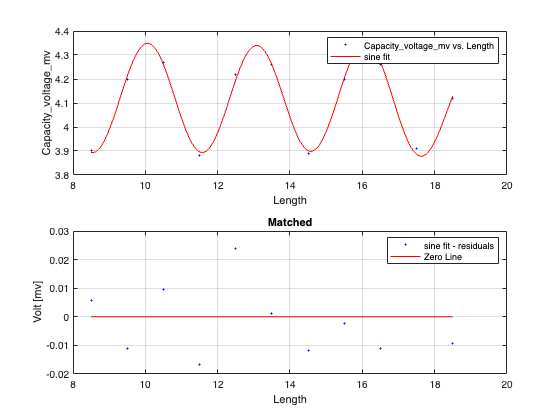

title('Matched')
ylabel('Volt [mv]')


figure;
Sine_sum_fit(Length,abs(Open_voltage_mv))

ans =      General model Sin3:
     ans(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3)
     Coefficients (with 95% confidence bounds):
       a1 =      -13.36  (-2.434e+06, 2.434e+06)
       b1 =      0.1208  (-2020, 2020)
       c1 =       3.069  (-2.808e+04, 2.808e+04)
       a2 =      -9.736  (-2.434e+06, 2.434e+06)
       b2 =      0.1413  (-2383, 2383)
       c2 =       5.926  (-3.303e+04, 3.305e+04)
       a3 =      -1.138  (-1.231, -1.046)
       b3 =        2.09  (2.039, 2.142)
       c3 =       7.855  (7.116, 8.595)

open_coe=9.736/13.36

open_coe = 0.7287

SWR_open=(1+open_coe)/(1-open_coe)

SWR_open = 6.3731

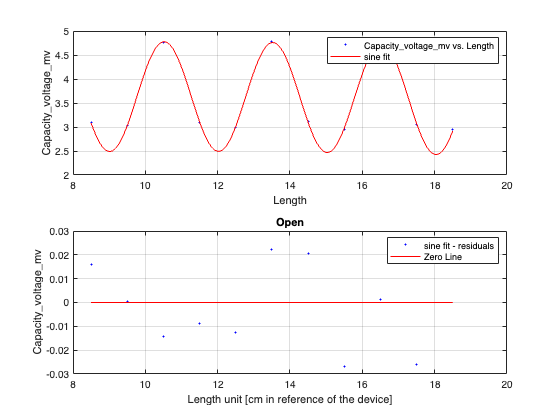

title('Open')
xlabel('Length unit [cm in reference of the device]')

figure;
Sine2sum(Length,short_voltage_mv_8Ghz)

ans =      General model Sin2:
     ans(x) =  a1*sin(b1*x+c1) + a2*sin(b2*x+c2)
     Coefficients (with 95% confidence bounds):
       a1 =       10.72  (10.14, 11.29)
       b1 =     0.03252  (-0.1153, 0.1803)
       c1 =       4.215  (2.431, 5.999)
       a2 =       9.523  (8.922, 10.12)
       b2 =       1.882  (1.858, 1.906)
       c2 =       1.519  (1.185, 1.854)

short8_coe=9.523/10.72

short8_coe = 0.8883

SWR_short8=(1+short8_coe)/(1-short8_coe)

SWR_short8 = 16.9114

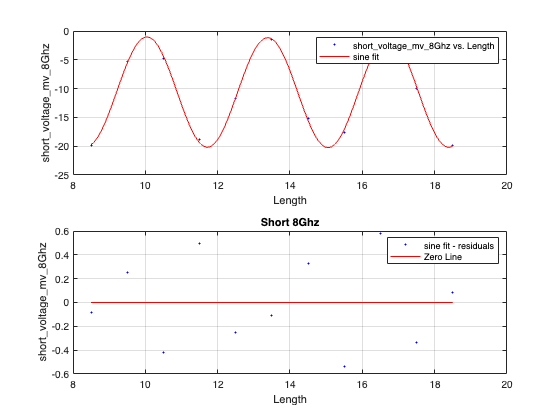

title('Short 8Ghz')

## Section 2 - Cutoff freq

Max_values_mv=[-20.4,-9.69,-15.8,-28,-70,-32.7,-1.12,-31.2,-1,-0.322,-0.400]

Max_values_mv =   -20.4000   -9.6900  -15.8000  -28.0000  -70.0000  -32.7000   -1.1200  -31.2000   -1.0000   -0.3220   -0.4000


freq_Ghz = [8,7.5,7,6.9,6.8,6.6,6.5,6.4,6,5.8,5.5]

freq_Ghz =     8.0000    7.5000    7.0000    6.9000    6.8000    6.6000    6.5000    6.4000    6.0000    5.8000    5.5000


T4 = table(freq_Ghz', Max_values_mv', 'VariableNames', {'freq_Ghz', 'Max_values_mv'})

T4 = 11×2 table
    freq_Ghz    Max_values_mv
    ________    _____________

        8           -20.4    
      7.5           -9.69    
        7           -15.8    
      6.9             -28    
      6.8             -70    
      6.6           -32.7    
      6.5           -1.12    
      6.4           -31.2    
        6              -1    
      5.8          -0.322    
      5.5            -0.4    


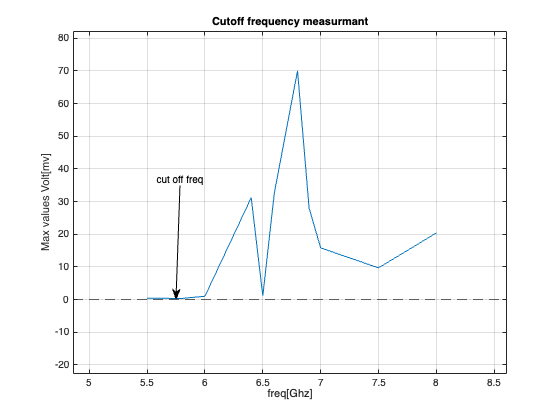

figure;
plot(freq_Ghz,abs(Max_values_mv))
title('Cutoff frequency measurmant')
xlabel('freq[Ghz]')
ylabel('Max values Volt[mv]')
hold on 
yline(0,'--')
grid on
annotation("textarrow", [0.3214 0.3143], [0.5585 0.2881], "String", "cut off freq")
xlim([4.86 8.61])
ylim([-22.8 82.2])

## Functions

function P = Volt_to_power(Volt)
  a = 30.78;b=0.2316;
  P = a*exp(Volt*b); 
end